# DYSKR

%INPUTS___________________________________________
A = [0 1; -6 -5];
B = [0; 6];
C = [1 0];
D = 0;
x0 = [1; 1];
h = 0.1;
t = 0:0.1:2;
i_max = max(t/h);

syms t_s;
syms h_s
disp("Analityc solution")

Analityc solution


y = expm(A.*t_s)*x0

$$y = \left(\begin{array}{c} 4\,{\mathrm{e}}^{-2\,t_{s}}-3\,{\mathrm{e}}^{-3\,t_{s}}\\ 9\,{\mathrm{e}}^{-3\,t_{s}}-8\,{\mathrm{e}}^{-2\,t_{s}} \end{array}\right)$$

disp("Analityc dicrete matrix")

Analityc dicrete matrix


A_plus_s = expm(A.*h_s)

$$A\_plus\_s = \left(\begin{array}{cc} 3\,{\mathrm{e}}^{-2\,h_{s}}-2\,{\mathrm{e}}^{-3\,h_{s}} & {\mathrm{e}}^{-2\,h_{s}}-{\mathrm{e}}^{-3\,h_{s}}\\ 6\,{\mathrm{e}}^{-3\,h_{s}}-6\,{\mathrm{e}}^{-2\,h_{s}} & 3\,{\mathrm{e}}^{-3\,h_{s}}-2\,{\mathrm{e}}^{-2\,h_{s}} \end{array}\right)$$

B_plus_s = inv(A)*(expm(A*h_s) - eye(2, 2))*B

$$B\_plus\_s = \left(\begin{array}{c} 2\,{\mathrm{e}}^{-3\,h_{s}}-3\,{\mathrm{e}}^{-2\,h_{s}}+1\\ 6\,{\mathrm{e}}^{-2\,h_{s}}-6\,{\mathrm{e}}^{-3\,h_{s}} \end{array}\right)$$

A_plus = subs(A_plus_s, h_s, h);
%A_plus = double(A_plus)
B_plus = subs(B_plus_s, h_s, h);
%B_plus = double(B_plus)

syscmodel = ss(A, B, C, D);
sysdmodel = c2d(syscmodel,h);
disp("Discrete model")

Discrete model


A_discr = sysdmodel.A

A_discr =     0.9746    0.0779
   -0.4675    0.5850


B_discr = sysdmodel.B

B_discr =     0.0254
    0.4675


C_discr = sysdmodel.C

C_discr =      1     0


D_discr = sysdmodel.D

D_discr = 0

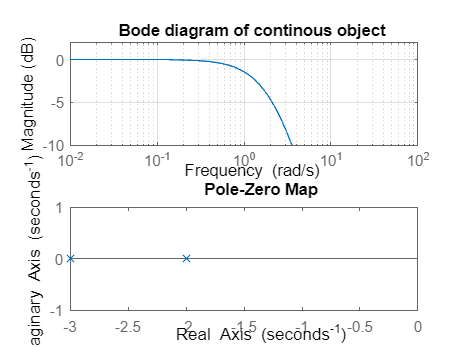


figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(syscmodel,opts1), grid on, hold all
title("Bode diagram of continous object")
subplot(2, 1, 2)
pzmap(syscmodel)

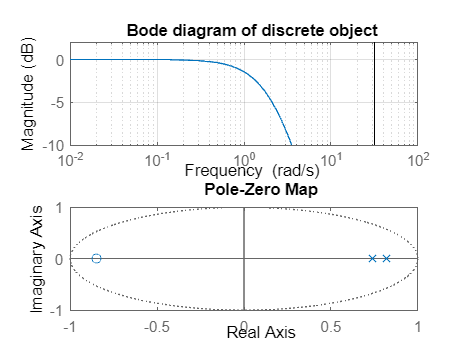


figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(sysdmodel,opts1), grid on, hold all
title("Bode diagram of discrete object")
subplot(2, 1, 2)
pzmap(sysdmodel)

Nomeric solving

%biezesz ciagle macierzeeee!!!!!!!!!!!!!!!!
euler_forw = @(A, h, x) (eye(2, 2) + h*A)*x; %h*B*u(i);
euler_back = @(A, h, x) ((eye(2, 2) - h*A)^-1)*x; % + ((eye(2, 2) - h*A)^-1)*h*B*u(i+1);  
NewtonColes = @(A, h, x) (eye(2, 2) + 0.5*h*A)*((eye(2, 2) - 0.5*h*A)^-1)*x; %...
                         %+ 0.5*h*((eye(2, 2) - 0.5*h*A)^-1)*B*(u(i+1) + u(i));

discrete_isstable =  @(A, h) pzmap(h*A)

discrete_isstable = function_handle with value:
    @(A,h)pzmap(h*A)



y_num = double(subs(y, t_s, t))

Unrecognized function or variable 'y'.


t_numh = 0:h:max(t);

disp("check difference models feasibility by checking zeros of matrixes")


### Can insert syms here

%euler_forw(A, h, x)
%euler_back(A, h, x)
%NewtonColes(A, h, x)
%syms h
%syms g
%syms x
%assume([h, g, x], 'positive')
%A = [1, 2*g; g, 13]

disp("isstable_euler_forw")

isstable_euler_forw


disp("eig should be in circle r=1 re=-1, im = 0")

eig should be in circle r=1 re=-1, im = 0


disp("isstable_euler_back")

isstable_euler_back


disp("eig should be in circle r=1 re=1, im = 0")

eig should be in circle r=1 re=1, im = 0


eig_val = eig(h*A)

$$eig\_val = \left(\begin{array}{c} 7\,h+\sqrt{2}\,h\,\sqrt{g^{2}+18}\\ 7\,h-\sqrt{2}\,h\,\sqrt{g^{2}+18} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} x\,\left(h+1\right) & 2\,g\,h\,x\\ g\,h\,x & x\,\left(13\,h+1\right) \end{array}\right)$$

$$ans = \begin{array}{l} \left(\begin{array}{cc} \frac{x\,\left(13\,h-1\right)}{\sigma_{1}} & -\frac{2\,g\,h\,x}{\sigma_{1}}\\ -\frac{g\,h\,x}{\sigma_{1}} & \frac{x\,\left(h-1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,g^{2}\,h^{2}-13\,h^{2}+14\,h-1 \end{array}$$

$$ans = \begin{array}{l} \left(\begin{array}{cc} x\,\left(\frac{2\,\left(\frac{h}{2}+1\right)\,\left(13\,h-2\right)}{\sigma_{2}}-\frac{\sigma_{3}}{\sigma_{2}}\right) & x\,\left(\frac{2\,g\,h\,\left(h-2\right)}{\sigma_{2}}-\frac{4\,g\,h\,\left(\frac{h}{2}+1\right)}{\sigma_{2}}\right)\\ x\,\left(\frac{g\,h\,\left(13\,h-2\right)}{\sigma_{2}}-\frac{2\,g\,h\,\sigma_{1}}{\sigma_{2}}\right) & -x\,\left(\frac{\sigma_{3}}{\sigma_{2}}-\frac{2\,\sigma_{1}\,\left(h-2\right)}{\sigma_{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{13\,h}{2}+1\\ \sigma_{2}=\sigma_{3}-13\,h^{2}+28\,h-4\\ \sigma_{3}=2\,g^{2}\,h^{2} \end{array}$$

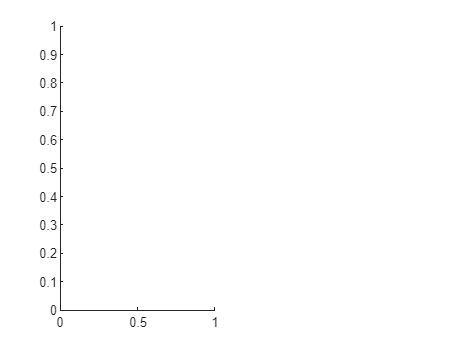


figure
subplot(1, 2, 1)

plot(real(eig_val), imag(eig_val), 'x' , LineWidth=3)

Error using plot
Data must be numeric, datetime, duration or an array convertible to double.

hold on;
theta = linspace(0, 2*pi, 100);
x0_e = -1;
v = 1;
x = x0_e + v*cos(theta);
y = v*sin(theta);
plot(x, y)
hold off;

subplot(1, 2, 2)
plot(real(eig_val), imag(eig_val), 'x' , LineWidth=3)
hold on;
theta = linspace(0, 2*pi, 100);
x0_e = 1;
v = 1;
x = x0_e + v*cos(theta);
y = v*sin(theta);
plot(x, y)


disp("isstable_NewtonColess")
disp("eig should have negative re")
eig(A)

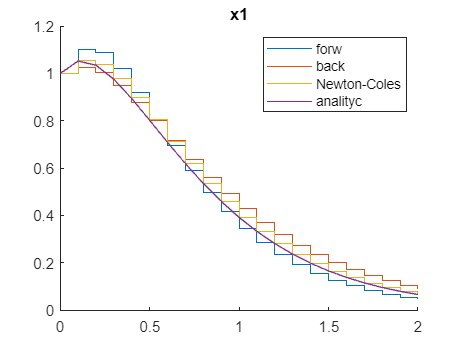

x_forw = [];
x_forw(:, 1) = x0;
x_back = [];
x_back(:, 1) = x0;
x_NC = [];
x_NC(:, 1) = x0;
for i = 1:i_max
    x_forw(:, i+1) = euler_forw(A, h, x_forw(:, i));
    x_back(:, i+1) = euler_back(A, h, x_back(:, i));
    x_NC(:, i+1) = NewtonColes(A, h, x_NC(:, i));
end

figure
hold on;
stairs(t_numh, x_forw(1, :))
stairs(t_numh, x_back(1, :))
stairs(t_numh, x_NC(1, :))
plot(t, y_num(1, :))
legend(["forw", "back", "Newton-Coles", "analityc"])
title("x1")
hold off;